axlabels = {'1L2/3e','1L2/3i','1L4e','1L4i','1L5e','1L5i','1L6e','1L6i', ...
    '2L2/3e','2L2/3i','2L4e','2L4i','2L5e','2L5i','2L6e','2L6i'};
cond = 4;
strt_prd = head(cond)+150000;
end_prd = tail(cond)+150000;

% plot the heatmap of pathway current
figure()
i = 196707

i = 196761

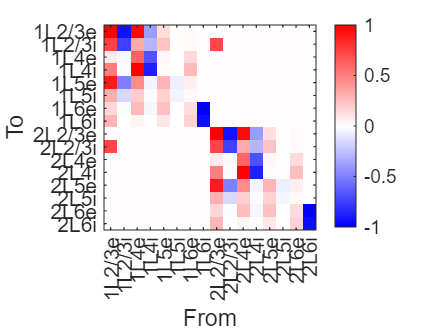

imagesc(pc(:,:,i,cond))
J = customcolormap([0 0.5 1], [1 0 0;1 1 1;0 0 1]);
colorbar; colormap(J);
clim([-1 1]); % colorbar axis
cap = num2str(i);
% title("Pathway current, "+"t = "+cap+" ms", 'FontSize', 14);
xlabel("From")
ylabel("To")
xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
xticklabels(axlabels);
yticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
yticklabels(axlabels);

% plot the heatmap of potential difference
figure()
i = 193565

i = 92540

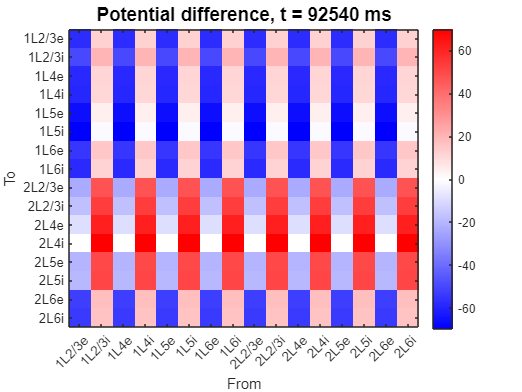

imagesc(pd(:,:,i))
J = customcolormap([0 0.5 1], [1 0 0;1 1 1;0 0 1]);
colorbar; colormap(J);
caxis([-70 70]); % colorbar axis
cap = num2str(i);
title("Potential difference, "+"t = "+cap+" ms", 'FontSize', 14);
xlabel("From")
ylabel("To")
xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
xticklabels(axlabels);
yticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
yticklabels(axlabels);

% plot the heatmap of gsyn
figure()
i = 193565

i = 92540

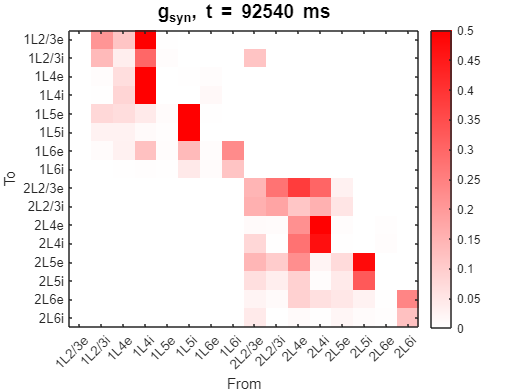

imagesc(g(:,:,i))
J = customcolormap([0 1], [1 0 0;1 1 1]);
colorbar; colormap(J);
caxis([0 0.5]); % colorbar axis
cap = num2str(i);
title("g_{syn}, "+"t = "+cap+" ms", 'FontSize', 14);
xlabel("From")
ylabel("To")
xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
xticklabels(axlabels);
yticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
yticklabels(axlabels);

% plot the heatmap of v_x;
figure()
i = 193565

i = 92540

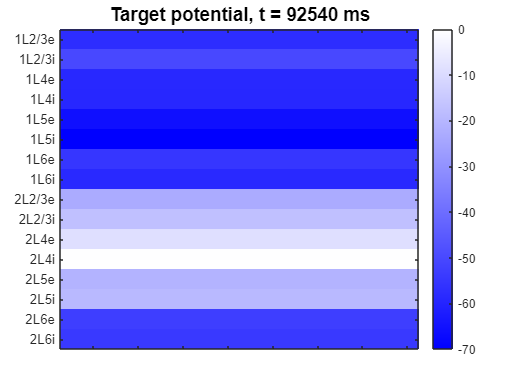

imagesc(v_x(:,:,i))
J = customcolormap([0 1], [1 1 1;0 0 1]);
colorbar; colormap(J);
caxis([-70 0]); % colorbar axis
cap = num2str(i);
title("Target potential, "+"t = "+cap+" ms", 'FontSize', 14);
% xlabel("From")
% ylabel("To")
% xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
xticklabels({});
yticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
yticklabels(axlabels);

% plot the heatmap of v_y;
figure()
i = 193565

i = 92540

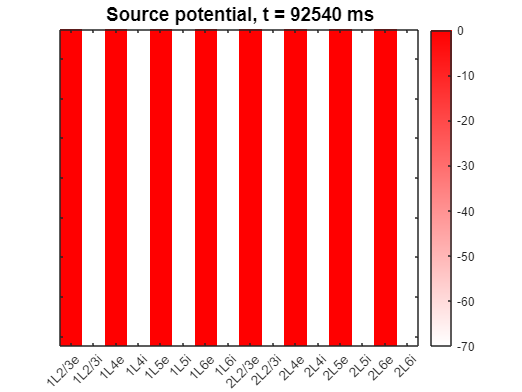

imagesc(v_y(:,:,i))
J = customcolormap([0 1], [1 0 0;1 1 1]);
colorbar; colormap(J);
caxis([-70 0]); % colorbar axis
cap = num2str(i);
title("Source potential, "+"t = "+cap+" ms", 'FontSize', 14);
% xlabel("From")
% ylabel("To")
% xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
yticklabels({});
xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
xticklabels(axlabels);

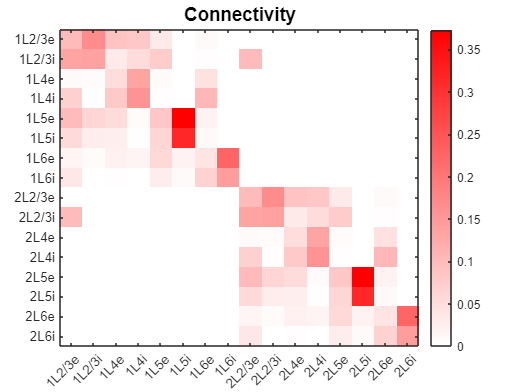

% plot the connectivity map;
figure()
imagesc(p);
J = customcolormap([0 1], [1 0 0;1 1 1]);
colorbar; colormap(J);
% caxis([-70 0]); % colorbar axis
title('Connectivity', 'FontSize', 14)
xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
xticklabels(axlabels);
yticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
yticklabels(axlabels);

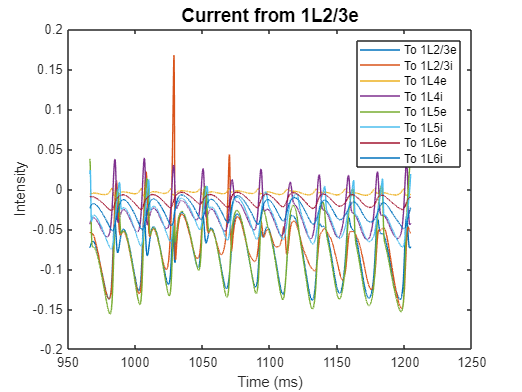

% Investigate by populations Current from 1L2/3e
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(i,1,strt_prd:end_prd));
    plot(plt_t,pc_stgh);
    hold on
end
title("Current from 1L2/3e", 'FontSize', 14)
legend('To 1L2/3e','To 1L2/3i','To 1L4e','To 1L4i', ...
    'To 1L5e','To 1L5i','To 1L6e','To 1L6i')
xlabel("Time (ms)")
ylabel("Intensity")

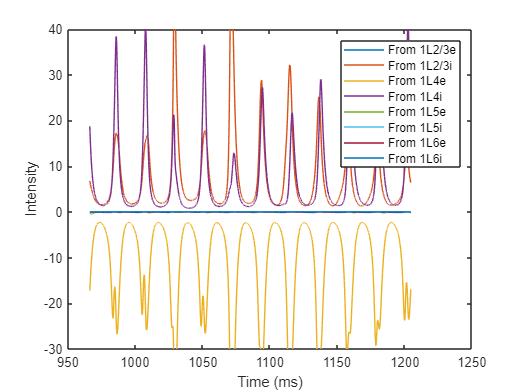

% Investigate by populations Current to 1L2/3e
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(1,i,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
% title("Current to 1L2/3e", 'FontSize', 14)
legend('From 1L2/3e','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")
ylim([-30 40])

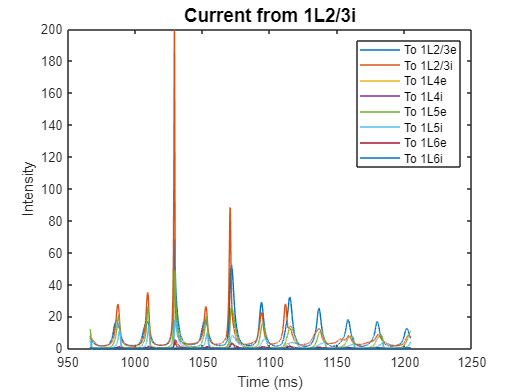

% Investigate by populations Curret from 1L2/3i
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(i,2,strt_prd:end_prd));
    plot(plt_t,pc_stgh);
    hold on
end
title("Current from 1L2/3i", 'FontSize', 14)
legend('To 1L2/3e','To 1L2/3i','To 1L4e','To 1L4i', ...
    'To 1L5e','To 1L5i','To 1L6e','To 1L6i')
xlabel("Time (ms)")
ylabel("Intensity")

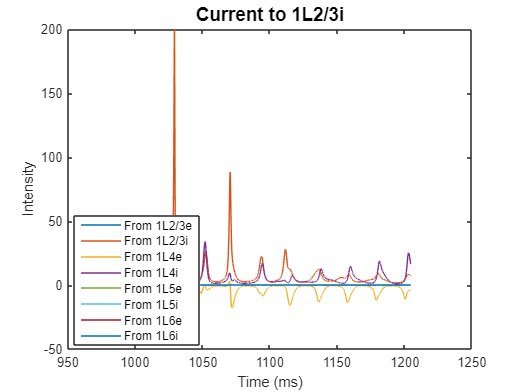

% Investigate by populations Current to 1L2/3i
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(2,i,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
title("Current to 1L2/3i", 'FontSize', 14)
legend('From 1L2/3e','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")

legend('Position',[0.14927,0.13165,0.22506,0.31006])

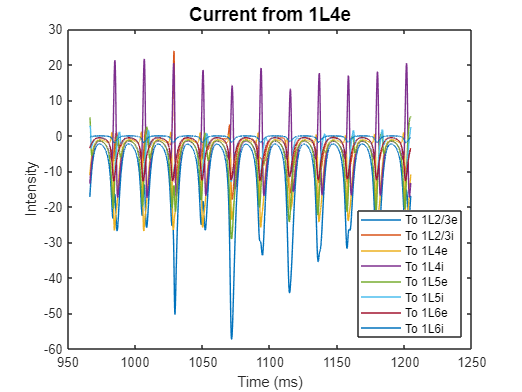

% Investigate by populations Current from 1L4e
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(i,3,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
title("Current from 1L4e", 'FontSize', 14)
legend('To 1L2/3e','To 1L2/3i','To 1L4e','To 1L4i', ...
    'To 1L5e','To 1L5i','To 1L6e','To 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")

legend('Position',[0.68748,0.14692,0.19708,0.31006])

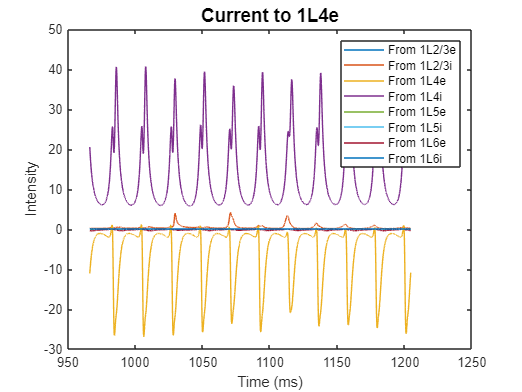

% Investigate by populations Current to 1L4e
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(3,i,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
title("Current to 1L4e", 'FontSize', 14)
legend('From 1L2/3e','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")

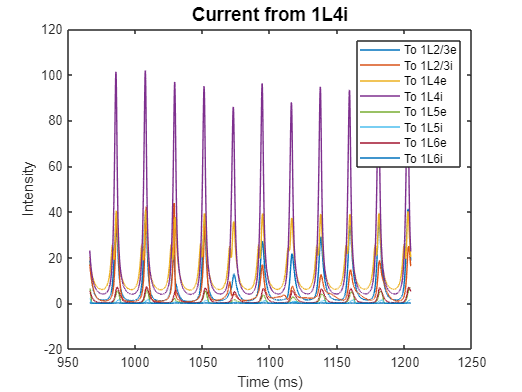

% Investigate by populations Current from 1L4i
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(i,4,strt_prd:end_prd));
    plot(plt_t,pc_stgh);
    hold on
end
title("Current from 1L4i", 'FontSize', 14)
legend('To 1L2/3e','To 1L2/3i','To 1L4e','To 1L4i', ...
    'To 1L5e','To 1L5i','To 1L6e','To 1L6i')
xlabel("Time (ms)")
ylabel("Intensity")

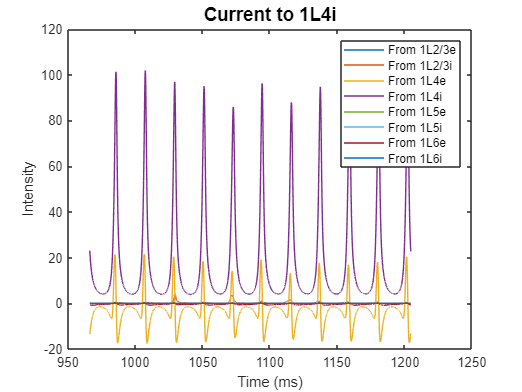

% Investigate by populations Current to 1L4i
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(4,i,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
title("Current to 1L4i", 'FontSize', 14)
legend('From 1L2/3e','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")

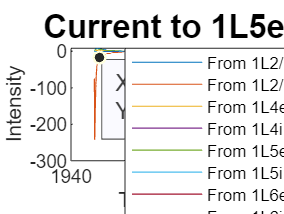

% Investigate by populations Current from 1L5e
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(5,i,strt_prd:end_prd,cond));
    plot(plt_t,pc_stgh);
    hold on
end
title("Current to 1L5e", 'FontSize', 14)
legend('From 1L2/3e','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i')
xlabel("Time (ms)")
ylabel("Intensity")


% legend('Position',[0.22669,0.15222,0.19708,0.31006])

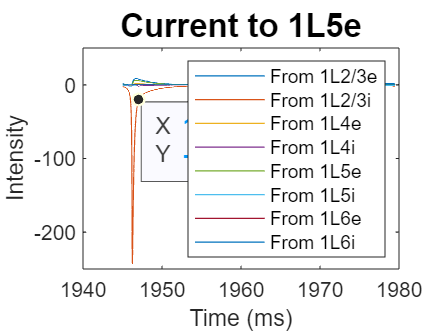

% Investigate by populations Current to 1L5e
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(5,i,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
title("Current to 1L5e", 'FontSize', 14)
legend('From 1L2/3e','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")

legend('Position',[0.1435,0.59328,0.22506,0.31006])

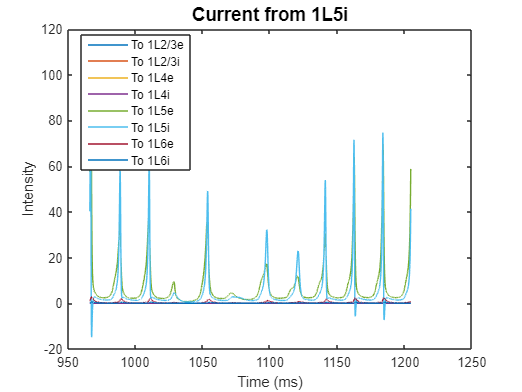

% Investigate by populations Current from 1L5i
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(i,6,strt_prd:end_prd));
    plot(plt_t,pc_stgh);
    hold on
end
title("Current from 1L5i", 'FontSize', 14)
legend('To 1L2/3e','To 1L2/3i','To 1L4e','To 1L4i', ...
    'To 1L5e','To 1L5i','To 1L6e','To 1L6i')
xlabel("Time (ms)")
ylabel("Intensity")

legend('Position',[0.16139,0.58421,0.19708,0.31006])

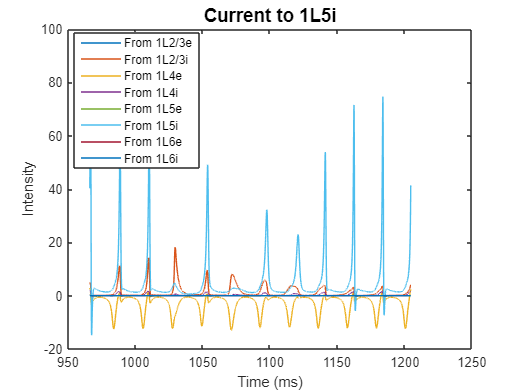

% Investigate by populations Current to 1L5i
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(6,i,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
title("Current to 1L5i", 'FontSize', 14)
legend('From 1L2/3e','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")

legend('Position',[0.1495,0.58929,0.22506,0.31006])

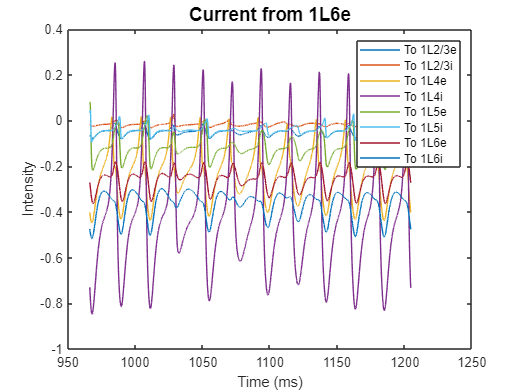

% Investigate by populations Current from 1L6e
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(i,7,strt_prd:end_prd));
    plot(plt_t,pc_stgh);
    hold on
end
title("Current from 1L6e", 'FontSize', 14)
legend('To 1L2/3e','To 1L2/3i','To 1L4e','To 1L4i', ...
    'To 1L5e','To 1L5i','To 1L6e','To 1L6i')
xlabel("Time (ms)")
ylabel("Intensity")

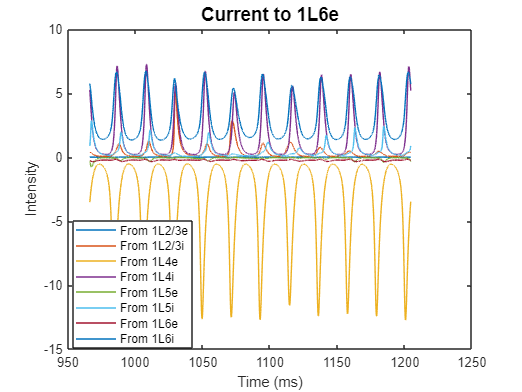

% Investigate by populations Current to 1L6e
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(7,i,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
title("Current to 1L6e", 'FontSize', 14)
legend('From 1L2/3e','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")

legend('Position',[0.14238,0.12009,0.22506,0.31006])

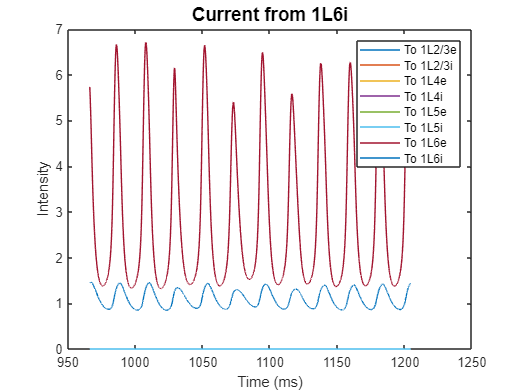

% Investigate by populations Current from 1L6i
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(i,8,strt_prd:end_prd));
    plot(plt_t,pc_stgh);
    hold on
end
title("Current from 1L6i", 'FontSize', 14)
legend('To 1L2/3e','To 1L2/3i','To 1L4e','To 1L4i', ...
    'To 1L5e','To 1L5i','To 1L6e','To 1L6i')
xlabel("Time (ms)")
ylabel("Intensity")

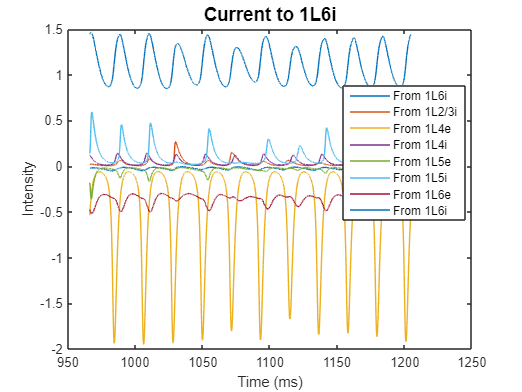

% Investigate by populations Current to 1L6i
figure()
plt_t = timeax(strt_prd:end_prd);
for i = 1:8
    pc_stgh = squeeze(pc(8,i,strt_prd:end_prd));
    plot(plt_t,pc_stgh); % minus for reverse direction
    hold on
end
title("Current to 1L6i", 'FontSize', 14)
legend('From 1L6i','From 1L2/3i','From 1L4e','From 1L4i', ...
    'From 1L5e','From 1L5i','From 1L6e','From 1L6i');
xlabel("Time (ms)")
ylabel("Intensity")

legend('Position',[0.66579,0.45556,0.21898,0.31006])

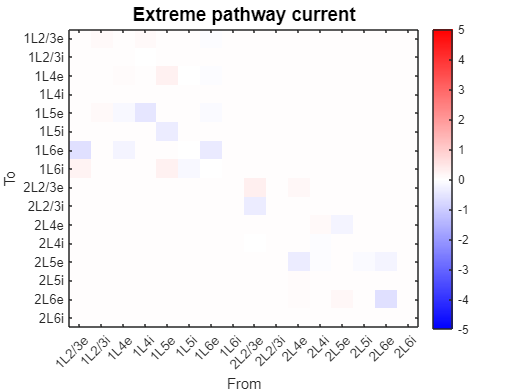

% get the extreme intensity of each pathway
[tmp_max, index_max] = max(abs(pc(:,:,strt_prd:end_prd)),[],3);
pc_max = pc(strt_prd+index_max);
figure()
imagesc(pc_max); % ?????
J = customcolormap([0 0.5 1], [1 0 0;1 1 1;0 0 1]);
colorbar; colormap(J);
caxis([-5 5]); % colorbar axis
cap = num2str(i);
title("Extreme pathway current", 'FontSize', 14);
xlabel("From")
ylabel("To")
xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
xticklabels(axlabels);
yticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
yticklabels(axlabels);

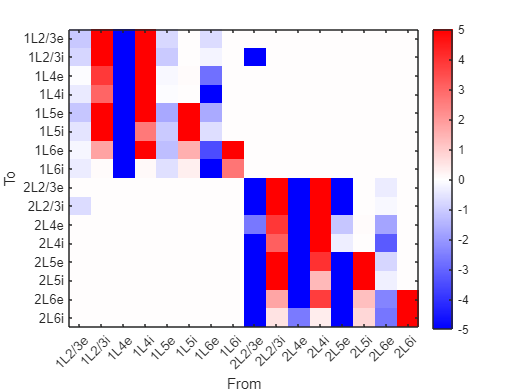

% obtain the energy transmission of all pathways by integration: (I^2/g)dt
tmp_pc = pc(:,:,strt_prd:end_prd);
tmp_g = g(:,:,strt_prd:end_prd);
idx_neg = tmp_pc < 0;
idx_pos = tmp_pc >= 0;
tmp_wn = -((tmp_pc .* idx_neg).^2) ./ tmp_g;
tmp_wn = tmp_wn * dt * 0.001; % dt*ms
tmp_wn = sum(tmp_wn, 3);
tmp_wp = ((tmp_pc .* idx_pos).^2) ./ tmp_g;
tmp_wp = tmp_wp * dt * 0.001;
tmp_wp = sum(tmp_wp, 3);

w = tmp_wp + tmp_wn;
w(isnan(w)) = 0;

figure()
imagesc(w);
J = customcolormap([0 0.5 1], [1 0 0;1 1 1;0 0 1]);
colorbar; colormap(J);
caxis([-5 5]); % colorbar axis
cap = num2str(i);
% title("Energy transmission", 'FontSize', 14);
xlabel("From")
ylabel("To")
xticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
xticklabels(axlabels);
yticks([1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16])
yticklabels(axlabels);

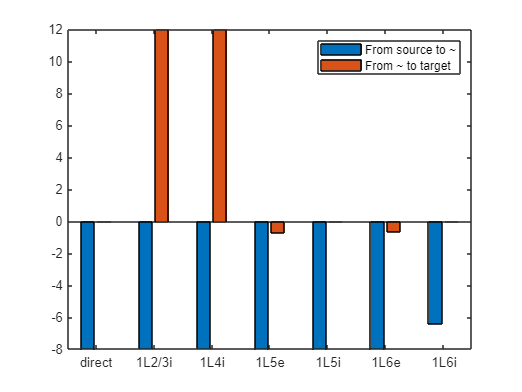

% Search pathways with defined source and target
%    1        2       3      4      5      6      7      8
% '1L2/3e','1L2/3i','1L4e','1L4i','1L5e','1L5i','1L6e','1L6i',
%    9        10      11     12     13     14     15     16
% '2L2/3e','2L2/3i','2L4e','2L4i','2L5e','2L5i','2L6e','2L6i'.
src = 3; % 3 for 1L4e % 9 for 2L2/3e
tgt = 1; % 1 for 1L2/3e
str1 = axlabels;
str1(:,[src,tgt]) = [];
str1 = [{"direct"},str1(:)'];
onlycol1 = 1; % only show column 1 on bar graph
onlycol2 = 0;

% find intermediary
egy = zeros(15,2);
egy(1,1) = w(tgt,src);
tmp_w = w(:,src);
tmp_w([src,tgt],:) = [];
egy(2:15,1) = tmp_w;

tmp_w = w(tgt,:);
tmp_w(:,[src,tgt]) = [];
egy(2:15,2) = tmp_w;


% bar graph
figure()
if onlycol1 == 1 && onlycol2 == 0
    h = bar(egy(1:7,:));
    % title("Energy transmission from "+axlabels(src)+" to "+axlabels(tgt));
    set(gca,'xticklabel',str1(1:7));
elseif onlycol1 == 0 && onlycol2 == 1
    egy([2:9],:) = [];
    h = bar(egy);
    % title("Energy transmission from "+axlabels(src)+" to "+axlabels(tgt));
    set(gca,'xticklabel',[str1(1),str1(10:15)]);
else
    h = bar(egy);
    % title("Energy transmission from "+axlabels(src)+" to "+axlabels(tgt));
    set(gca,'xticklabel',str1);
end
% set 3 display names for the 3 handles
set(h, {'DisplayName'}, {'From source to ~','From ~ to target'}')
% Legend will show names for each color
legend() 
ylim([[-8 12]]);